# Technical Note: An improved methodology  for calculating the Southern Annular Mode Index to aid consistency between climate studies

#### Author: Laura Velasquez

#### Aim: Calculate the natural and normalised SAM indices reconstructions and future scenarios based on sea level pressure

Key: normal = normalised SAM, dimensional =  natural SAM. 

1. Natural (dimensional) SAM index calculation. Calibration interval 196-1991

1.a. Daily resolution

% 40S data
msl_40="iera5_slp_daily_0-360E_-40N_n.nc"

msl_40 = "iera5_slp_daily_0-360E_-40N_n.nc"

msl_40=ncread(msl_40, "msl");

%msl_40=0.875*msl_40%use this line if you want to calculate the weighted values
msl_40=msl_40/100; %pass pressure data to hPa

% Create time variable
t1=datetime(1950, 01, 01);
t2=datetime(2022, 12, 31);
t=t1:t2;
t=t';
t=convertTo(t,'yyyymmdd');
% Separate month and year 
yeartime=floor(t/1E4);%year 
monthtime=floor(t/ 1E2);%month 

% combined time and msl data into one table 
daily_40=table(t,yeartime, msl_40);
%select calibration interval data
interval=daily_40.msl_40(daily_40.t>19601231 & daily_40.t<19910101);
format long%this shows the hole number
mean_40=mean(interval);%calculate the mean
norm_40=msl_40-mean_40;%substract calibration interval mean

%Load 65S data
msl_65='iera5_slp_daily_0-360E_-65N_n.nc'

msl_65 = 'iera5_slp_daily_0-360E_-65N_n.nc'

msl_65=ncread(msl_65, 'msl')

msl_65 = 1.0e+05 *

   0.994688281250000
   0.996906093750000
   0.997604218750000
   0.995335468750000
   0.994460468750000
   0.995603437500000
   0.996246093750000
   0.994203828125000
   0.991642187500000
   0.989969062500000


%msl_65=0.650*msl_65;%use this code to calcualte the weighted values
msl_65=msl_65/100;

%Combined dates and msl in one table
daily_65=table(t,yeartime, msl_65);
%set calibration interval
interval_65=daily_65.msl_65(daily_65.t>19601231 & daily_65.t<19910101);
mean_65=mean(interval_65);%calculate the calibration interval mean
norm_65=msl_65-mean_65;%substract mean

%calculate the daily SAM by subtracting 65 to 40
daily_sam_1=norm_40-norm_65

daily_sam_1 =  -12.369028560507104
 -13.202778560506999
 -14.134966060507054
 -12.404184810507104
 -11.480200435507072
 -12.325122310507140
 -11.482778560507086
  -8.538559810507081
  -5.671919185507022
  -3.877778560507068


%calculate annual average daily SAM
daily_sam=daily_sam_1

daily_sam =  -12.369028560507104
 -13.202778560506999
 -14.134966060507054
 -12.404184810507104
 -11.480200435507072
 -12.325122310507140
 -11.482778560507086
  -8.538559810507081
  -5.671919185507022
  -3.877778560507068


daily_sam=table(yeartime, daily_sam)%table of year and daily sam

daily_sam = 26663×2 table
    yeartime        daily_sam    
    ________    _________________

      1950      -12.3690285605071
      1950       -13.202778560507
      1950      -14.1349660605071
      1950      -12.4041848105071
      1950      -11.4802004355071
      1950      -12.3251223105071
      1950      -11.4827785605071
      1950      -8.53855981050708
      1950      -5.67191918550702
      1950      -3.87777856050707
      1950      -4.30496606050713
      1950      -3.96684106050714
      1950      -6.16020043550714
      1950      -8.18426293550715
      1950      -8.36246606050702
      1950      -7.24449731050709


daily_sam=grpstats(daily_sam, "yeartime")%calculate annual mean to plot

daily_sam = 73×3 table
            yeartime    GroupCount      mean_daily_sam  
            ________    __________    __________________

    1950      1950         365         -1.64338386872625
    1951      1951         365         -3.98810433105502
    1952      1952         366        -0.423479337487949
    1953      1953         365          -1.2525268481783
    1954      1954         365         0.622904444629911
    1955      1955         365         -2.07523275571255
    1956      1956         366         -2.95233542526117
    1957      1957         365         -4.11453284132899
    1958      1958         365         -1.32467624886324
    1959      1959         365        -0.522558526260498
    1960

daily_sam.Properties.VariableNames=["Year", "G", "d_daily_sam"]

daily_sam = 73×3 table
            Year     G        d_daily_sam    
            ____    ___    __________________

    1950    1950    365     -1.64338386872625
    1951    1951    365     -3.98810433105502
    1952    1952    366    -0.423479337487949
    1953    1953    365      -1.2525268481783
    1954    1954    365     0.622904444629911
    1955    1955    365     -2.07523275571255
    1956    1956    366     -2.95233542526117
    1957    1957    365     -4.11453284132899
    1958    1958    365     -1.32467624886324
    1959    1959    365    -0.522558526260498
    1960    1960    366      2.71638405049019
    1961    1961    365      1.45361912784909
    1962 

1.b. Montlhy resolution 

% Group daily data into monthly data
month_msl_40=table(monthtime, yeartime, msl_40)

month_msl_40 = 26663×3 table
    monthtime    yeartime        msl_40    
    _________    ________    ______________

     195001        1950       1012.02796875
     195001        1950       1013.41203125
     195001        1950       1013.17796875
     195001        1950             1012.64
     195001        1950      1012.688984375
     195001        1950       1012.98703125
     195001        1950       1014.47203125
     195001        1950      1015.373984375
     195001        1950      1015.678984375
     195001        1950              1015.8
     195001        1950      1015.971015625
     195001        1950      1015.633984375
     195001        1950      1014.468984375
     195001        1950      1014.763984375
     195001        1950      1015.278984375
     195001        1950      1015.688984375


month_msl_40=grpstats(month_msl_40, "monthtime")%group the daily mean to monthly means

month_msl_40 = 876×4 table
              monthtime    GroupCount    mean_yeartime      mean_msl_40   
              _________    __________    _____________    ________________

    195001     195001          31            1950         1013.51176915323
    195002     195002          28            1950         1017.16900669643
    195003     195003          31            1950         1017.40728578629
    195004     195004          30            1950         1016.54473958333
    195005     195005          31            1950         1013.60238659274
    195006     195006          30            1950         1014.22483854167
    195007     195007          31            1950         1018.08350554435
    195008     195008    

%calibration interval
month_interval=month_msl_40.mean_msl_40(month_msl_40.monthtime>196012& month_msl_40.monthtime<199101)

month_interval = 1.0e+03 *

   1.015271643145161
   1.016099860491072
   1.017182454637097
   1.018014302083333
   1.015591325604839
   1.015249440104167
   1.015255995463710
   1.015458359375000
   1.017641502604167
   1.018386066028226


m_mean_40=mean(month_interval)%calculate the mean of the calibration interval

m_mean_40 =      1.015669760479760e+03


m_norm_40=month_msl_40.mean_msl_40-m_mean_40%subatract the mean

m_norm_40 =   -2.157991326534329
   1.499246216668325
   1.737525306530188
   0.874979103572855
  -2.067373887018562
  -1.444921938093557
   2.413745064594650
   0.436910387175317
   1.691067645239855
   1.189919459755970


%now lat 65
month_msl_65=table(monthtime, yeartime, msl_65)

month_msl_65 = 26663×3 table
    monthtime    yeartime       msl_65    
    _________    ________    _____________

     195001        1950       994.68828125
     195001        1950       996.90609375
     195001        1950       997.60421875
     195001        1950       995.33546875
     195001        1950       994.46046875
     195001        1950        995.6034375
     195001        1950       996.24609375
     195001        1950      994.203828125
     195001        1950        991.6421875
     195001        1950        989.9690625
     195001        1950      990.567265625
     195001        1950      989.892109375
     195001        1950       990.92046875
     195001        1950       993.23953125
     195001        1950      993.932734375
     195001        1950      993.224765625


month_msl_65=grpstats(month_msl_65, "monthtime")%group daily means to monthly means

month_msl_65 = 876×4 table
              monthtime    GroupCount    mean_yeartime      mean_msl_65   
              _________    __________    _____________    ________________

    195001     195001          31            1950         992.495498991936
    195002     195002          28            1950         985.140979352678
    195003     195003          31            1950         989.551628024193
    195004     195004          30            1950         988.673994791667
    195005     195005          31            1950         992.073424899194
    195006     195006          30            1950         988.670981770833
    195007     195007          31            1950         985.903591229839
    195008     195008    

%calibration interval
month_interval_65=month_msl_65.mean_msl_65(month_msl_65.monthtime>196012& month_msl_65.monthtime<199101)

month_interval_65 = 1.0e+03 *

   0.987452651209678
   0.988309079241071
   0.984238054435484
   0.986543046875000
   0.986625128528226
   0.988643445312500
   0.987944377520161
   0.986084032258065
   0.988516734375000
   0.977847996471774


m_mean_65=mean(month_interval_65)%calculate the mean of the calibration interval

m_mean_65 =      9.859485981089031e+02


m_norm_65=month_msl_65.mean_msl_65-m_mean_65%substract the mean

m_norm_65 =    6.546900883032549
  -0.807618756224656
   3.603029915290335
   2.725396682763630
   6.124826790290513
   2.722383661930053
  -0.045006879064545
   3.277331830613093
  -0.268743942236483
   0.908559149161533


%calculate monthly sam
monthly_sam_1=m_norm_40-m_norm_65

monthly_sam_1 =   -8.704892209566879
   2.306864972892981
  -1.865504608760148
  -1.850417579190776
  -8.192200677309074
  -4.167305600023610
   2.458751943659195
  -2.840421443437776
   1.959811587476338
   0.281360310594437


%Now I get year from the monthtime variable. This is so I have the same
%number of 'years' when data is averaged by month
yearmonthtime=floor(month_msl_65.monthtime/1E2)%now I can average the monthly sam into year

yearmonthtime =         1950
        1950
        1950
        1950
        1950
        1950
        1950
        1950
        1950
        1950


monthly_sam=monthly_sam_1

monthly_sam =   -8.704892209566879
   2.306864972892981
  -1.865504608760148
  -1.850417579190776
  -8.192200677309074
  -4.167305600023610
   2.458751943659195
  -2.840421443437776
   1.959811587476338
   0.281360310594437


monthly_sam=table(yearmonthtime, monthly_sam)%put time and sam in one table

monthly_sam = 876×2 table
    yearmonthtime       monthly_sam   
    _____________    _________________

        1950         -8.70489220956688
        1950          2.30686497289298
        1950         -1.86550460876015
        1950         -1.85041757919078
        1950         -8.19220067730907
        1950         -4.16730560002361
        1950          2.45875194365919
        1950         -2.84042144343778
        1950          1.95981158747634
        1950         0.281360310594437
        1950         0.567014712476521
        1950         0.661509000110641
        1951          2.42656948398155
        1951          3.74261274075013
        1951          2.31209871785279
        1951         -3.11979257919052


monthly_sam=grpstats(monthly_sam, "yearmonthtime")%calculate annual means for monthly SAM.

monthly_sam = 73×3 table
            yearmonthtime    GroupCount     mean_monthly_sam 
            _____________    __________    __________________

    1950        1950             12         -1.61545246592318
    1951        1951             12         -3.95962229379221
    1952        1952             12        -0.433310157315428
    1953        1953             12          -1.2288388146494
    1954        1954             12         0.636736611177791
    1955        1955             12         -2.02967801335819
    1956        1956             12         -2.95901848751049
    1957        1957             12          -4.0962581229852
    1958        1958             12         -1.33628508071042
    1959        1959

monthly_sam.Properties.VariableNames=["Year", "G", "d_monthly_sam"]

monthly_sam = 73×3 table
            Year    G       d_monthly_sam   
            ____    __    __________________

    1950    1950    12     -1.61545246592318
    1951    1951    12     -3.95962229379221
    1952    1952    12    -0.433310157315428
    1953    1953    12      -1.2288388146494
    1954    1954    12     0.636736611177791
    1955    1955    12     -2.02967801335819
    1956    1956    12     -2.95901848751049
    1957    1957    12      -4.0962581229852
    1958    1958    12     -1.33628508071042
    1959    1959    12    -0.511744416608006
    1960    1960    12      2.70722709279272
    1961    1961    12      1.41216498409363
    1962    1962    1

1.c. Annual resolution

% Group daily data into annual data
annual_msl_40=table(yeartime, msl_40)

annual_msl_40 = 26663×2 table
    yeartime        msl_40    
    ________    ______________

      1950       1012.02796875
      1950       1013.41203125
      1950       1013.17796875
      1950             1012.64
      1950      1012.688984375
      1950       1012.98703125
      1950       1014.47203125
      1950      1015.373984375
      1950      1015.678984375
      1950              1015.8
      1950      1015.971015625
      1950      1015.633984375
      1950      1014.468984375
      1950      1014.763984375
      1950      1015.278984375
      1950      1015.688984375


annual_msl_40=grpstats(annual_msl_40, "yeartime")

annual_msl_40 = 73×3 table
            yeartime    GroupCount      mean_msl_40   
            ________    __________    ________________

    1950      1950         365        1015.90382684075
    1951      1951         365        1014.33857534247
    1952      1952         366          1015.357678236
    1953      1953         365        1015.58868214897
    1954      1954         365        1016.24915796233
    1955      1955         365        1015.04545355308
    1956      1956         366         1014.5026020321
    1957      1957         365        1014.47534888699
    1958      1958         365        1015.17853060788
    1959      1959         365        1015.84158732877
    1960      1960     

%calibration interval
year_interval=annual_msl_40.mean_msl_40(annual_msl_40.yeartime>1960 & annual_msl_40.yeartime<1991)

year_interval = 1.0e+03 *

   1.016573916523973
   1.015712788527398
   1.016009387628424
   1.014753173027664
   1.015240386772260
   1.015622041952055
   1.015952417594178
   1.015257468621926
   1.015837456335617
   1.015387159246576


a_mean_40=mean(year_interval)%calculate the mean of the calibration interval

a_mean_40 =      1.015662984282755e+03


a_norm_40=annual_msl_40.mean_msl_40-a_mean_40%substract the mean

a_norm_40 =    0.240842557997894
  -1.324408940289572
  -0.305306046758119
  -0.074302133782794
   0.586173679573221
  -0.617530729673376
  -1.160382250651878
  -1.187635395769121
  -0.484453674878864
   0.178603046011858


%65 
annual_msl_65=table(yeartime, msl_65)

annual_msl_65 = 26663×2 table
    yeartime       msl_65    
    ________    _____________

      1950       994.68828125
      1950       996.90609375
      1950       997.60421875
      1950       995.33546875
      1950       994.46046875
      1950        995.6034375
      1950       996.24609375
      1950      994.203828125
      1950        991.6421875
      1950        989.9690625
      1950      990.567265625
      1950      989.892109375
      1950       990.92046875
      1950       993.23953125
      1950      993.932734375
      1950      993.224765625


annual_msl_65=grpstats(annual_msl_65, "yeartime")

annual_msl_65 = 73×3 table
            yeartime    GroupCount      mean_msl_65   
            ________    __________    ________________

    1950      1950         365        987.838494648972
    1951      1951         365        988.617963613014
    1952      1952         366        986.072441512978
    1953      1953         365        987.132492936644
    1954      1954         365        985.917537457192
    1955      1955         365        987.411970248288
    1956      1956         366        987.746221396858
    1957      1957         365        988.881165667808
    1958      1958         365        986.794490796233
    1959      1959         365        986.655429794521
    1960      1960     

%calibration interval
year_interval_65=annual_msl_65.mean_msl_65(annual_msl_65.yeartime>1960 & annual_msl_65.yeartime<1991)

year_interval_65 = 1.0e+02 *

   9.854115813356163
   9.851572185359586
   9.865476967037674
   9.885922720286885
   9.877567093321916
   9.867963854880140
   9.861147369434930
   9.868821055327869
   9.872084360017123
   9.855598499571919


a_mean_65=mean(year_interval_65)%calculate the mean of the calibration interval

a_mean_65 =      9.859531402963746e+02


a_norm_65=annual_msl_65.mean_msl_65-a_mean_65%substract mean

a_norm_65 =    1.885354352597687
   2.664823316639172
   0.119301216603617
   1.179352640269258
  -0.035602839182957
   1.458829951912890
   1.793081100483391
   2.928025371433705
   0.841350499858208
   0.702289498146115


% Calculate annual SAM index
annual_sam=a_norm_40-a_norm_65

annual_sam =   -1.644511794599794
  -3.989232256928744
  -0.424607263361736
  -1.253654774052052
   0.621776518756178
  -2.076360681586266
  -2.953463351135269
  -4.115660767202826
  -1.325804174737073
  -0.523686452134257


% combined sam and time in one table
annual_sam=table(annual_msl_65.yeartime, annual_sam)

annual_sam = 73×2 table
    Var1           Var2       
    ____    __________________

    1950     -1.64451179459979
    1951     -3.98923225692874
    1952    -0.424607263361736
    1953     -1.25365477405205
    1954     0.621776518756178
    1955     -2.07636068158627
    1956     -2.95346335113527
    1957     -4.11566076720283
    1958     -1.32580417473707
    1959    -0.523686452134257
    1960      2.71525612461653
    1961      1.45249120197548
    1962     0.845726005057941
    1963    -0.248153061723883
    1964     -3.54894298740544
    1965     -2.22616654631236


%name columns
annual_sam.Properties.VariableNames=["Year", "d_annual_sam"]

annual_sam = 73×2 table
    Year       d_annual_sam   
    ____    __________________

    1950     -1.64451179459979
    1951     -3.98923225692874
    1952    -0.424607263361736
    1953     -1.25365477405205
    1954     0.621776518756178
    1955     -2.07636068158627
    1956     -2.95346335113527
    1957     -4.11566076720283
    1958     -1.32580417473707
    1959    -0.523686452134257
    1960      2.71525612461653
    1961      1.45249120197548
    1962     0.845726005057941
    1963    -0.248153061723883
    1964     -3.54894298740544
    1965     -2.22616654631236


% put the three natural SAMs in one table
dimensional_sams=table(daily_sam.Year, daily_sam.d_daily_sam, monthly_sam.d_monthly_sam, annual_sam.d_annual_sam)

dimensional_sams = 73×4 table
    Var1           Var2                  Var3                  Var4       
    ____    __________________    __________________    __________________

    1950     -1.64338386872625     -1.61545246592318     -1.64451179459979
    1951     -3.98810433105502     -3.95962229379221     -3.98923225692874
    1952    -0.423479337487949    -0.433310157315428    -0.424607263361736
    1953      -1.2525268481783      -1.2288388146494     -1.25365477405205
    1954     0.622904444629911     0.636736611177791     0.621776518756178
    1955     -2.07523275571255     -2.02967801335819     -2.07636068158627
    1956     -2.95233542526117     -2.95901848751049     -2.95346335113527
    1957     -4.11453284132899      -4.0962581229852     -4.11566076720283
    1958     -1.32467624886324     -1.33628508071042     -1.32580417473707
    1959

dimensional_sams.Properties.VariableNames=["Year", "d_Daily SAM", "d_Monthly SAM", "d_Annual SAM"]

dimensional_sams = 73×4 table
    Year       d_Daily SAM          d_Monthly SAM          d_Annual SAM   
    ____    __________________    __________________    __________________

    1950     -1.64338386872625     -1.61545246592318     -1.64451179459979
    1951     -3.98810433105502     -3.95962229379221     -3.98923225692874
    1952    -0.423479337487949    -0.433310157315428    -0.424607263361736
    1953      -1.2525268481783      -1.2288388146494     -1.25365477405205
    1954     0.622904444629911     0.636736611177791     0.621776518756178
    1955     -2.07523275571255     -2.02967801335819     -2.07636068158627
    1956     -2.95233542526117     -2.95901848751049     -2.95346335113527
    1957     -4.11453284132899      -4.0962581229852     -4.11566076720283
    1958     -1.32467624886324     -1.33628508071042     -1.32580417473707
    1959

2. Normalised (non-dimensional) SAM index

2. a. Daily resolution

%These will be calculated from the data that was already loaded for the dimensional SAMs 
%First daily SAM lat -40
std_40=std(interval)%calculate the sd of the calibration interval

std_40 =    2.524614261402456


normal_mean_40= norm_40/std_40 %normalise

normal_mean_40 =   -1.439711426318986
  -0.891484110502762
  -0.984196293737450
  -1.197285777633954
  -1.177883061049116
  -1.059826659500317
  -0.471617988297185
  -0.114354251500052
   0.006456283662905
   0.054390586677062


%now -65
std_65=std(interval_65)% sd from CI

std_65 =    5.597647123431392


normal_mean_65=norm_65/std_65%calculate sam

normal_mean_65 =    1.560354264697545
   1.956558678998029
   2.081276258474895
   1.675972038688851
   1.519656361636379
   1.723843714786174
   1.838651996878456
   1.473808415286606
   1.016180313958615
   0.717282408623277


%now calculate SAM index
normal_daily_sam_1=normal_mean_40-normal_mean_65

normal_daily_sam_1 =   -3.000065691016531
  -2.848042789500791
  -3.065472552212345
  -2.873257816322806
  -2.697539422685495
  -2.783670374286491
  -2.310269985175641
  -1.588162666786658
  -1.009724030295710
  -0.662891821946215


%calculate annual average
normal_daily_sam=normal_daily_sam_1

normal_daily_sam =   -3.000065691016531
  -2.848042789500791
  -3.065472552212345
  -2.873257816322806
  -2.697539422685495
  -2.783670374286491
  -2.310269985175641
  -1.588162666786658
  -1.009724030295710
  -0.662891821946215


normal_daily_sam=table(yeartime, normal_daily_sam)%table of year and daily sam

normal_daily_sam = 26663×2 table
    yeartime     normal_daily_sam 
    ________    __________________

      1950       -3.00006569101653
      1950       -2.84804278950079
      1950       -3.06547255221234
      1950       -2.87325781632281
      1950        -2.6975394226855
      1950       -2.78367037428649
      1950       -2.31026998517564
      1950       -1.58816266678666
      1950       -1.00972403029571
      1950      -0.662891821946215
      1950      -0.702019400595373
      1950      -0.714903224621896
      1950       -1.36007264974005
      1950       -1.65751548694658
      1950       -1.57736223136651
      1950       -1.28848505325462


normal_daily_sam=grpstats(normal_daily_sam, "yeartime")%calculate annual mean

normal_daily_sam = 73×3 table
            yeartime    GroupCount    mean_normal_daily_sam
            ________    __________    _____________________

    1950      1950         365          -0.241147534194236 
    1951      1951         365           -1.00039322609885 
    1952      1952         366          -0.141977869029993 
    1953      1953         365          -0.239851656469257 
    1954      1954         365           0.238810418899576 
    1955      1955         365          -0.504952206146963 
    1956      1956         366          -0.779688550013011 
    1957      1957         365          -0.993237332085081 
    1958      1958         365          -0.341929833841845 
    1959      1959         365       

normal_daily_sam.Properties.VariableNames=["Year", "G", "Daily_SAM"]%change column names

normal_daily_sam = 73×3 table
            Year     G          Daily_SAM     
            ____    ___    ___________________

    1950    1950    365     -0.241147534194236
    1951    1951    365      -1.00039322609885
    1952    1952    366     -0.141977869029993
    1953    1953    365     -0.239851656469257
    1954    1954    365      0.238810418899576
    1955    1955    365     -0.504952206146963
    1956    1956    366     -0.779688550013011
    1957    1957    365     -0.993237332085081
    1958    1958    365     -0.341929833841845
    1959    1959    365    -0.0544502306724616
    1960    1960    366      0.669192365107728
    1961    1961    365       0.45783460683944
    <

2.b. Monthly resolution

%==============================
%%Normal montly sam index
m_std_40=std(month_interval)% sd of CI

m_std_40 =    1.694070423727526


normal_m_mean_40=m_norm_40/m_std_40% normalise

normal_m_mean_40 =   -1.273849833105533
   0.884996394287717
   1.025651166677620
   0.516495118099994
  -1.220358881226226
  -0.852929085978753
   1.424819789536020
   0.257905681520587
   0.998227477178272
   0.702402593829450


%now -65
m_std_65=std(month_interval_65)

m_std_65 =    4.025243809747239


normal_m_mean_65=m_norm_65/m_std_65

normal_m_mean_65 =    1.626460704610997
  -0.200638469219923
   0.895108491705645
   0.677076175153417
   1.521603927558146
   0.676327643890222
  -0.011181156022291
   0.814194614168946
  -0.066764637109860
   0.225715308712837


%calculate SAM index
normal_monthly_sam_1=normal_m_mean_40-normal_m_mean_65

normal_monthly_sam_1 =   -2.900310537716531
   1.085634863507640
   0.130542674971975
  -0.160581057053424
  -2.741962808784371
  -1.529256729868975
   1.436000945558311
  -0.556288932648360
   1.064992114288132
   0.476687285116613


%calcualte annual average
normal_monthly_sam=normal_monthly_sam_1

normal_monthly_sam =   -2.900310537716531
   1.085634863507640
   0.130542674971975
  -0.160581057053424
  -2.741962808784371
  -1.529256729868975
   1.436000945558311
  -0.556288932648360
   1.064992114288132
   0.476687285116613


normal_monthly_sam=table(yearmonthtime, normal_monthly_sam)% combine in a table

normal_monthly_sam = 876×2 table
    yearmonthtime    normal_monthly_sam
    _____________    __________________

        1950          -2.90031053771653
        1950           1.08563486350764
        1950          0.130542674971975
        1950         -0.160581057053424
        1950          -2.74196280878437
        1950          -1.52925672986898
        1950           1.43600094555831
        1950          -0.55628893264836
        1950           1.06499211428813
        1950          0.476687285116613
        1950         -0.174544941106602
        1950          0.047064565001485
        1951          0.726254614982513
        1951           1.32551154273285
        1951           0.72905783367463
        1951           -1.3816447792557


normal_monthly_sam=grpstats(normal_monthly_sam, "yearmonthtime")%calculate annual means

normal_monthly_sam = 73×3 table
            yearmonthtime    GroupCount    mean_normal_monthly_sam
            _____________    __________    _______________________

    1950        1950             12           -0.318501879894509  
    1951        1951             12            -1.43310942569716  
    1952        1952             12           -0.214919239952878  
    1953        1953             12           -0.334043136150413  
    1954        1954             12            0.362784265727482  
    1955        1955             12           -0.713544963246059  
    1956        1956             12            -1.13437887810146  
    1957        1957             12            -1.42476729029004  
    1958        1958             12       

normal_monthly_sam.Properties.VariableNames=["Year", "G", "Monthly_SAM"]

normal_monthly_sam = 73×3 table
            Year    G         Monthly_SAM    
            ____    __    ___________________

    1950    1950    12     -0.318501879894509
    1951    1951    12      -1.43310942569716
    1952    1952    12     -0.214919239952878
    1953    1953    12     -0.334043136150413
    1954    1954    12      0.362784265727482
    1955    1955    12     -0.713544963246059
    1956    1956    12      -1.13437887810146
    1957    1957    12      -1.42476729029004
    1958    1958    12     -0.494218329940676
    1959    1959    12    -0.0669143048554987
    1960    1960    12      0.961812739713142
    1961    1961    12      0.660252737343103
    1962<

2.c. Annual resolution

%===============================
% Normal annual normal SAM
a_std_40=std(year_interval)

a_std_40 =    0.509860274073497


normal_a_mean_40=a_norm_40/a_std_40

normal_a_mean_40 =    0.472369726069648
  -2.597591943589345
  -0.598803362966279
  -0.145730384501545
   1.149675135287601
  -1.211176396897237
  -2.275882844099767
  -2.329335027968703
  -0.950169486648472
   0.350298022995438


%-65
a_std_65=std(year_interval_65)

a_std_65 =    1.355947047586986


normal_a_mean_65=a_norm_65/a_std_65

normal_a_mean_65 =    1.390433613136164
   1.965285680868906
   0.087983684035393
   0.869763050384606
  -0.026256806448537
   1.075875311288145
   1.322382834694260
   2.159395071248804
   0.620489200780707
   0.517932834763639


%calculate annual SAM index
normal_annual_sam=normal_a_mean_40-normal_a_mean_65

normal_annual_sam =   -0.918063887066516
  -4.562877624458251
  -0.686787047001672
  -1.015493434886152
   1.175931941736138
  -2.287051708185382
  -3.598265678794027
  -4.488730099217507
  -1.570658687429179
  -0.167634811768202


%create a Table and name columns
normal_annual_sam=table(annual_msl_65.yeartime, normal_annual_sam)% combine in a table

normal_annual_sam = 73×2 table
    Var1           Var2       
    ____    __________________

    1950    -0.918063887066516
    1951     -4.56287762445825
    1952    -0.686787047001672
    1953     -1.01549343488615
    1954      1.17593194173614
    1955     -2.28705170818538
    1956     -3.59826567879403
    1957     -4.48873009921751
    1958     -1.57065868742918
    1959    -0.167634811768202
    1960      3.03721466661387
    1961      2.18602649821522
    1962     0.684668016085794
    1963      0.24092783541443
    1964     -3.73077086756082
    1965     -2.15896725385667


normal_annual_sam.Properties.VariableNames=["Year", "Annual SAM"]

normal_annual_sam = 73×2 table
    Year        Annual SAM    
    ____    __________________

    1950    -0.918063887066516
    1951     -4.56287762445825
    1952    -0.686787047001672
    1953     -1.01549343488615
    1954      1.17593194173614
    1955     -2.28705170818538
    1956     -3.59826567879403
    1957     -4.48873009921751
    1958     -1.57065868742918
    1959    -0.167634811768202
    1960      3.03721466661387
    1961      2.18602649821522
    1962     0.684668016085794
    1963      0.24092783541443
    1964     -3.73077086756082
    1965     -2.15896725385667


%%%put all normalised SAMs in one table
sam_index=table(normal_daily_sam.Year, normal_daily_sam.Daily_SAM, normal_monthly_sam.Monthly_SAM, normal_annual_sam.("Annual SAM"))

sam_index = 73×4 table
    Var1           Var2                   Var3                   Var4       
    ____    ___________________    ___________________    __________________

    1950     -0.241147534194236     -0.318501879894509    -0.918063887066516
    1951      -1.00039322609885      -1.43310942569716     -4.56287762445825
    1952     -0.141977869029993     -0.214919239952878    -0.686787047001672
    1953     -0.239851656469257     -0.334043136150413     -1.01549343488615
    1954      0.238810418899576      0.362784265727482      1.17593194173614
    1955     -0.504952206146963     -0.713544963246059     -2.28705170818538
    1956     -0.779688550013011      -1.13437887810146     -3.59826567879403
    1957     -0.993237332085081      -1.42476729029004     -4.48873009921751
    1958     -0.341929833841845     -0.494218329940676     -1.57065868

sam_index.Properties.VariableNames=["Year", "daily SAM", "monthly SAM", "annual SAM"]

sam_index = 73×4 table
    Year         daily SAM             monthly SAM            annual SAM    
    ____    ___________________    ___________________    __________________

    1950     -0.241147534194236     -0.318501879894509    -0.918063887066516
    1951      -1.00039322609885      -1.43310942569716     -4.56287762445825
    1952     -0.141977869029993     -0.214919239952878    -0.686787047001672
    1953     -0.239851656469257     -0.334043136150413     -1.01549343488615
    1954      0.238810418899576      0.362784265727482      1.17593194173614
    1955     -0.504952206146963     -0.713544963246059     -2.28705170818538
    1956     -0.779688550013011      -1.13437887810146     -3.59826567879403
    1957     -0.993237332085081      -1.42476729029004     -4.48873009921751
    1958     -0.341929833841845     -0.494218329940676     -1.57065868

#### Figures

%==============================================
%Figures comparing with in data resolutions
comparison=tiledlayout(3,1)

comparison =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [3 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


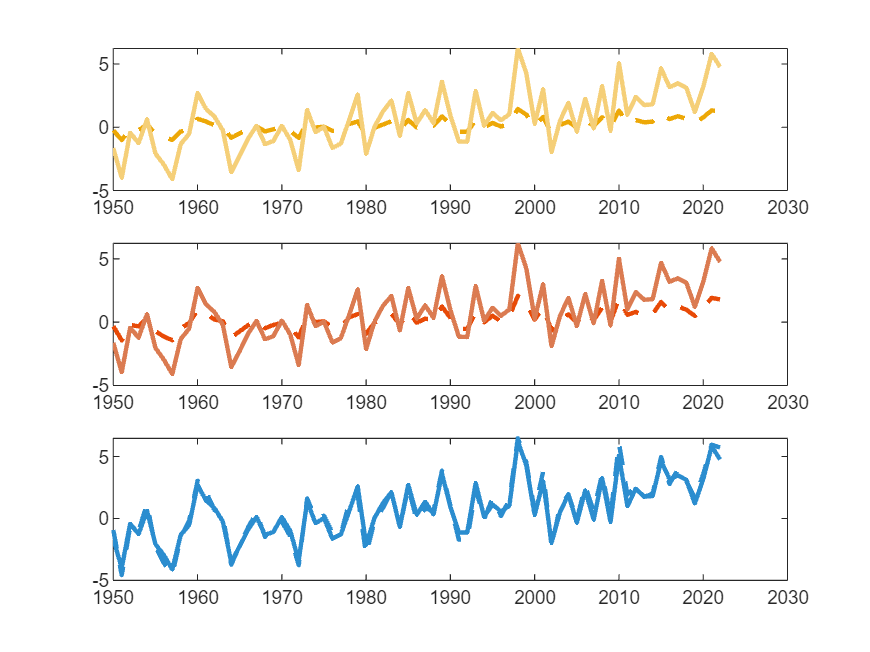

nexttile
%daily
plot(sam_index.Year, sam_index.("daily SAM"), "--", 'Color', [0.9294 0.6588 0.027], 'LineWidth',2)
hold on
plot(dimensional_sams.Year, dimensional_sams.("d_Daily SAM"), 'Color',[0.9607 0.8117 0.4705] , 'LineWidth',2)
nexttile
%monthly
plot(sam_index.Year, sam_index.("monthly SAM"),("--") ,'Color',[0.9098 0.2901 0.0274],'LineWidth',2)
hold on
plot(dimensional_sams.Year,dimensional_sams.("d_Monthly SAM"), 'Color',[0.8588 0.4823 0.3176],'LineWidth',2)
%annual
nexttile
plot(sam_index.Year, sam_index.("annual SAM"), "--",'Color', [0.1686 0.5529 0.8117], 'LineWidth',2)
hold on
plot(sam_index.Year, dimensional_sams.("d_Annual SAM"), 'Color', [0.1686 0.5529 0.8117], 'LineWidth',2)

%figure comparing annual SAM 
annual=tiledlayout(1,1)

annual =   TiledChartLayout with properties:

    TileArrangement: 'fixed'
           GridSize: [1 1]
            Padding: 'loose'
        TileSpacing: 'loose'

  Show all properties


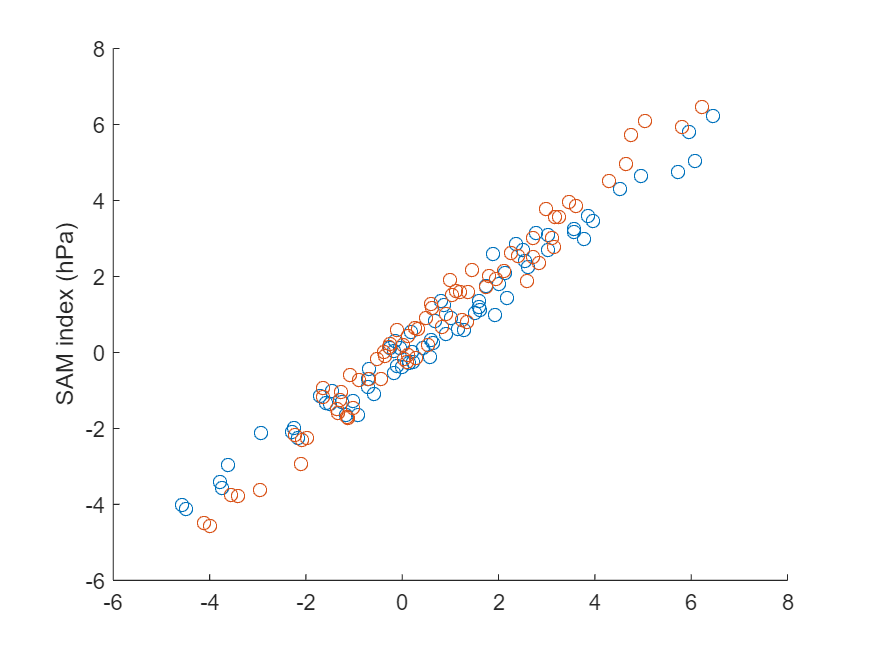

scatter(sam_index.("annual SAM"),dimensional_sams.("d_Annual SAM") ,'Color', [0.1686 0.5529 0.8117])
hold on 
scatter(dimensional_sams.("d_Annual SAM"), sam_index.("annual SAM") ,'Color', [0.9607 0.8117 0.4705])
ylabel('SAM index (hPa)')

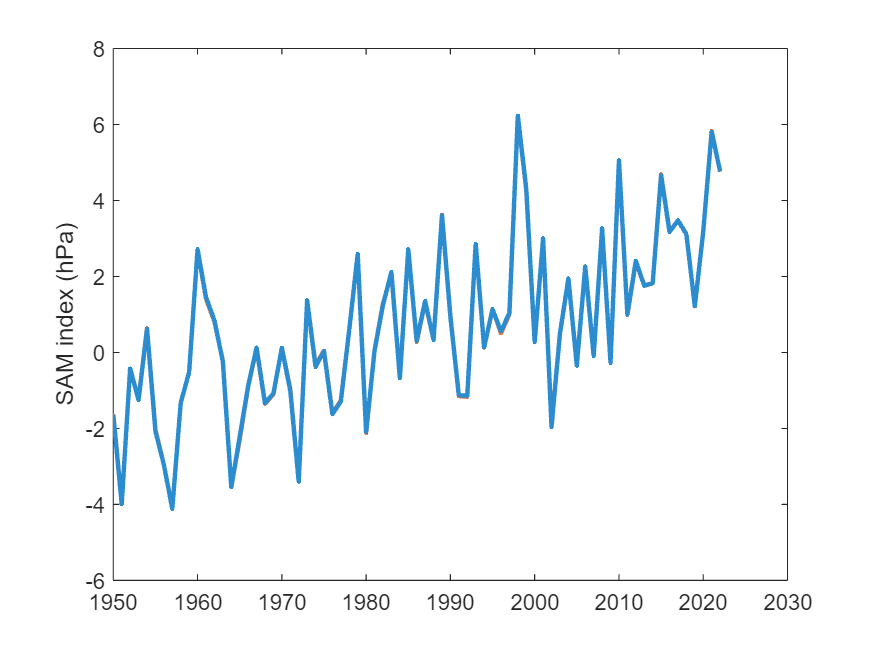

%===========================================
%Figure 3.d Daily, monthly and annual dimensional SAMs
tiledlayout(1,1)
nexttile;
plot(dimensional_sams.Year, dimensional_sams.("d_Daily SAM"), 'Color', [0.9607 0.8117 0.4705], 'LineWidth',2)
hold on
plot(dimensional_sams.Year, dimensional_sams.("d_Monthly SAM"), 'Color',[0.8588 0.4823 0.3176],'LineWidth',2)
hold on
plot(dimensional_sams.Year, dimensional_sams.("d_Annual SAM"), 'Color', [0.1686 0.5529 0.8117], 'LineWidth',2)
ylabel('SAM index (hPa)')

xticklabels()

ans = 9×1 cell array
    {'1950'}
    {'1960'}
    {'1970'}
    {'1980'}
    {'1990'}
    {'2000'}
    {'2010'}
    {'2020'}
    {'2030'}


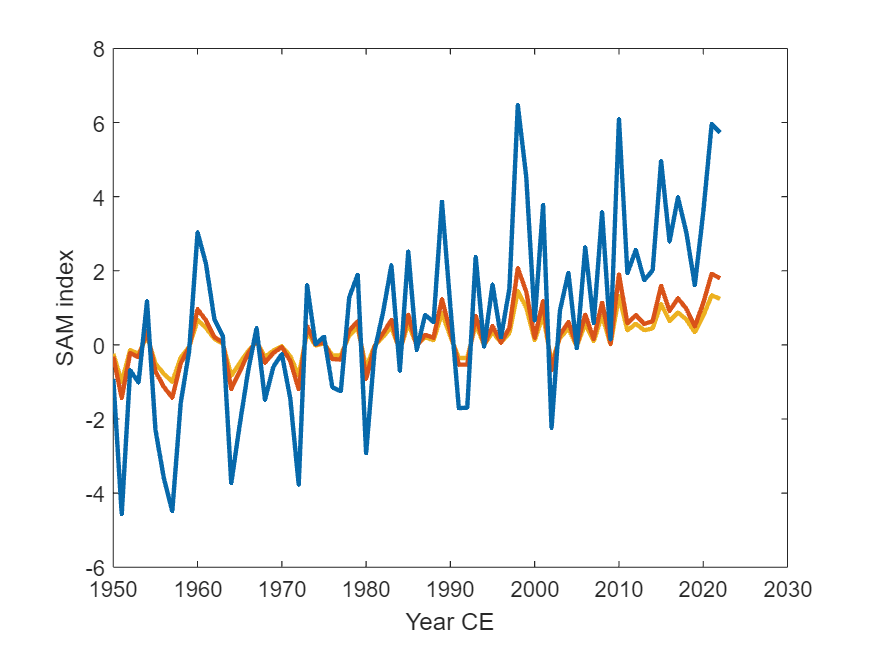

%Figure 3.a Daily, monthly and annual non-dimensional SAMs
tiledlayout(1,1)
nexttile;
plot(sam_index.Year, sam_index.("daily SAM"), 'Color', [0.9294 0.6941 0.1255], 'LineWidth',2)
hold on
plot(sam_index.Year, sam_index.("monthly SAM"), 'Color',[0.8510 0.3255 0.0980],'LineWidth',2)
hold on
plot(sam_index.Year, sam_index.("annual SAM"), 'Color', [0.0275 0.4118 0.6706], 'LineWidth',2)
xlabel('Year CE')
ylabel('SAM index')

%Figure 3.b Scatter plot for daily SAM vs. monthly SAM
r=corrcoef(sam_index.("daily SAM"), sam_index.("monthly SAM"));
r=r(1,2);
tiledlayout(1, 2)
nexttile
scatter(sam_index, 'daily SAM', 'monthly SAM', 'MarkerFaceColor',[0.4313 0.6509 0.8])
xlim([-1, 1.5])
ylim([-1.5, 2.5])
text(1.1,-1.3,sprintf('r= 0.9995 (n=73, p<0.001)',r))
hold on
p = polyfit(sam_index.("daily SAM"),sam_index.("monthly SAM"), 1);
slope = p(1)% this gives me the slope of the line

slope =    1.434398263408023


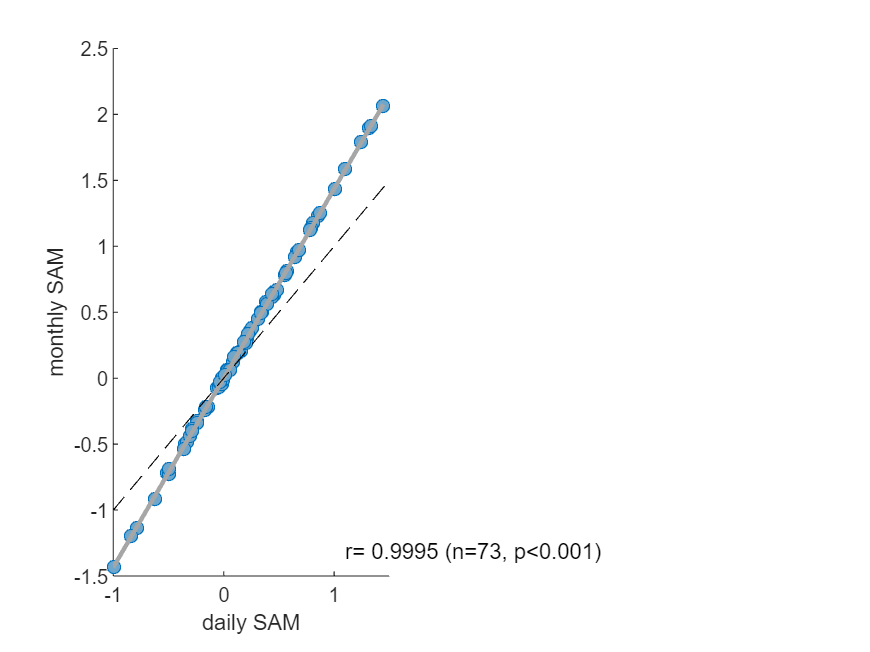

intercept=p(2);
plot(sam_index.("daily SAM"), slope*sam_index.("daily SAM")+intercept, 'LineWidth',2, 'Color',[0.6509 0.6509 0.6509])
hold on 
plot([-1 , 1.5], [-1, 1.5], 'k--')

%Figure 3.c Scatter plot for monthly SAM vs. annual SAM
nexttile
r2=corrcoef(sam_index.("monthly SAM"), sam_index.("annual SAM"));
r2=r2(1,2);
scatter(sam_index, 'monthly SAM', 'annual SAM','MarkerFaceColor',[0.4313 0.6509 0.8])
text(2,-3,sprintf('r= 0.9998 (n=73, p<0.001',r))
hold on
p = polyfit(sam_index.("monthly SAM"),sam_index.("annual SAM"), 1);
slope = p(1)%this gives me the slope

slope =    3.151933499130042


intercept=p(2)

intercept =    0.003760922165546


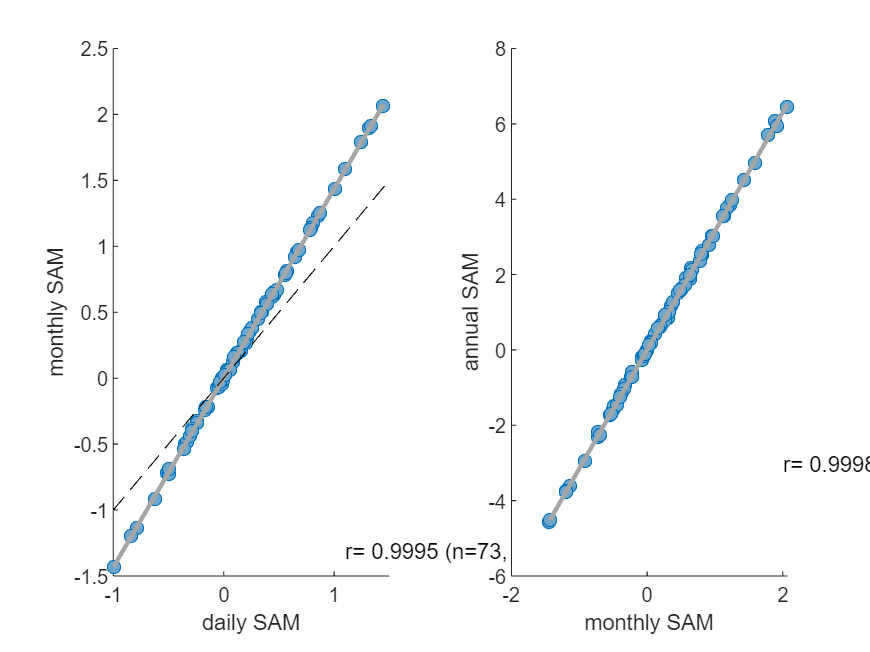

plot(sam_index.("monthly SAM"), slope*sam_index.("monthly SAM")+intercept, 'LineWidth',2, 'Color',[0.6509 0.6509 0.6509])

%Correlation coefficient and slope
%Correlation coefficient 
annual_coef = corr(dimensional_sams.("d_Annual SAM"),sam_index.("annual SAM"))

annual_coef =    0.986750979960501


annual_slope = polyfit(dimensional_sams.("d_Annual SAM"),sam_index.("annual SAM"),1);
annual_slope = annual_slope(1)

annual_slope =    1.070563597604152


%Adjust data to plot dimensional and non-dimensional in same plot
%calculate slope between both timelines
sca=polyfit(dimensional_sams.("d_Annual SAM"), sam_index.("annual SAM"),1)

sca = 1×2
   1.070563597604152   0.049283505948326


slope=sca(1)

slope =    1.070563597604152


max(dimensional_sams.("d_Annual SAM"))

ans =    6.231967229372799


min(dimensional_sams.("d_Annual SAM"))

ans =   -4.115660767202826


max(sam_index.("annual SAM"))

ans =    6.471445943685372


min(sam_index.("annual SAM"))

ans =   -4.562877624458251


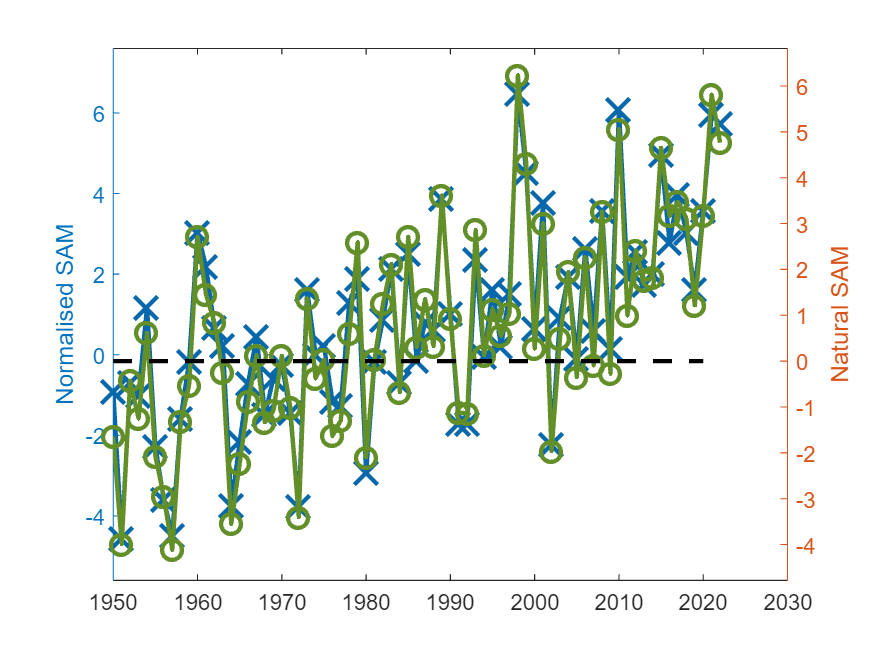

%Plot dimensional vs. non-dimensional annual SAMs
figure
yyaxis left;
plot(sam_index.Year, sam_index.("annual SAM"), '-x',"Color",[0.0275 0.4118 0.6706], 'LineWidth',2, 'MarkerSize', 15);
ylabel('Normalised SAM')
ylim([-5.6 7.6]);
yyaxis right;
plot(dimensional_sams.Year, dimensional_sams.("d_Annual SAM"), '-o', 'Color',[0.3843 0.5607 0.1568], 'LineWidth',2, 'MarkerSize', 9)
ylabel('Natural SAM')
%adjust y-axis based on the slope
ylim(([-5.12 7.3])/slope);
yZero = zeros(size(100));
line([min(1950), max(2020)], [0, 0], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 2);
hold off;

% Scale the right y-axis based on the slope
%yticklabels(gca, 'right', get(gca, 'right', 'YTickLabels') / slope_annual);

## Future scenario SAMs

Only annual resolution SAMs were calculted. Calibration period 1961 - 1990. 

3. High emissions

3. a. Normalised SAM index annual resolution

% Create date variables
startYear = 1850;
endYear = 2100;
numYears = endYear - startYear + 1;
allDates = NaT(numYears*12,1); % Preallocate a list of NaNs for all the dates

for y = startYear:endYear
    for m = 1:12
        allDates((y-startYear)*12 + m) = datetime(y,m,1);
    end
end

allDates

allDates = 3012×1 datetime array
   01-Jan-1850
   01-Feb-1850
   01-Mar-1850
   01-Apr-1850
   01-May-1850
   01-Jun-1850
   01-Jul-1850
   01-Aug-1850
   01-Sep-1850
   01-Oct-1850
   01-Nov-1850
   01-Dec-1850
   01-Jan-1851
   01-Feb-1851
   01-Mar-1851
   01-Apr-1851
   01-May-1851
   01-Jun-1851
   01-Jul-1851
   01-Aug-1851
   01-Sep-1851
   01-Oct-1851
   01-Nov-1851
   01-Dec-1851
   01-Jan-1852
   01-Feb-1852
   01-Mar-1852
   01-Apr-1852
   01-May-1852
   01-Jun-1852


f_time=convertTo(allDates,'yyyymmdd')

f_time = 3012×1
    18500101
    18500201
    18500301
    18500401
    18500501
    18500601
    18500701
    18500801
    18500901
    18501001


f_yeartime=floor(f_time/1E4)%extract only the year, it will be used later 

f_yeartime = 3012×1
        1850
        1850
        1850
        1850
        1850
        1850
        1850
        1850
        1850
        1850


%future_40=table(f_time, f_msl_40)%time and msl in one table

% msl data
f_msl_40="icmip6_psl_mon_one_ssp585_0-360E_-40N_n_001.nc"

f_msl_40 = "icmip6_psl_mon_one_ssp585_0-360E_-40N_n_001.nc"

f_msl_40=ncread(f_msl_40, "psl")

f_msl_40 = 3012×1
1.0e+05 *

   1.014600000000000
   1.015785000000000
   1.019523984375000
   1.019536015625000
   1.014187968750000
   1.016910000000000
   1.016692031250000
   1.017535000000000
   1.015938984375000
   1.016572031250000


%f_msl_40=f_msl_40*0.875 %include this line if calculating weighted values 
annual_f_msl_40=f_msl_40/100

annual_f_msl_40 = 3012×1
1.0e+03 *

   1.014600000000000
   1.015785000000000
   1.019523984375000
   1.019536015625000
   1.014187968750000
   1.016910000000000
   1.016692031250000
   1.017535000000000
   1.015938984375000
   1.016572031250000


annual_f_40=table(f_time, f_yeartime, annual_f_msl_40)

annual_f_40 = 3012×3 table
     f_time     f_yeartime    annual_f_msl_40
    ________    __________    _______________

    18500101       1850               1014.6 
    18500201       1850             1015.785 
    18500301       1850       1019.523984375 
    18500401       1850       1019.536015625 
    18500501       1850        1014.18796875 
    18500601       1850              1016.91 
    18500701       1850        1016.69203125 
    18500801       1850             1017.535 
    18500901       1850       1015.938984375 
    18501001       1850        1016.57203125 
    18501101       1850              1016.04 
    18501201       1850       1015.606015625 
    18510101       1851       1016.581015625 
    18510201       1851        1016.35796875 
    18510301       1851               1017.6 
    18510401       1851       1016.171015625 


annual_f_40=grpstats(annual_f_40, "f_yeartime")%calculate annual mean

annual_f_40 = 251×4 table
            f_yeartime    GroupCount    mean_f_time    mean_annual_f_msl_40
            __________    __________    ___________    ____________________

    1850       1850           12         18500651        1016.57725260417  
    1851       1851           12         18510651        1016.49974609375  
    1852       1852           12         18520651        1016.56848958333  
    1853       1853           12         18530651        1016.48391276042  
    1854       1854           12         18540651        1016.20666015625  
    1855       1855           12         18550651        1017.45225260417  
    1856       1856           12         18560651        1015.49016927083  
    1857       18

%calibration interval
annual_interval = annual_f_40.mean_annual_f_msl_40(annual_f_40.f_yeartime>1960 & annual_f_40.f_yeartime<1991)

annual_interval = 30×1
1.0e+03 *

   1.015541158854167
   1.016299505208333
   1.016840585937500
   1.017093261718750
   1.015846679687500
   1.016551341145833
   1.017683502604167
   1.016589752604167
   1.017003170572917
   1.015251497395833


annual_f_40_mean=mean(annual_interval)

annual_f_40_mean =      1.016675403428819e+03


annual_f_40_std=std(annual_interval)

annual_f_40_std =    0.593075609333479


annual_f_40_msl=(annual_f_40.mean_annual_f_msl_40 - annual_f_40_mean)/annual_f_40_std%normalise data

annual_f_40_msl = 251×1
  -0.165494623464903
  -0.296180339074713
  -0.180270177703267
  -0.322877328605558
  -0.790360057288871
   1.309865324288784
  -1.998453720458991
   1.931349724898558
   0.158788175765897
  -0.368268797236187


%moving standard deviation
movStd40High = movstd(annual_f_40.mean_annual_f_msl_40,7)

movStd40High = 251×1
   0.047369097610787
   0.151319801568649
   0.424305981402409
   0.579726814273121
   0.775986086139674
   0.774209361099491
   0.778132274514554
   0.774948414888037
   0.742367911850117
   0.696417166335271


%%now for high emissions 65S
f_msl_65="icmip6_psl_mon_one_ssp585_0-360E_-65N_n_001.nc"

f_msl_65 = "icmip6_psl_mon_one_ssp585_0-360E_-65N_n_001.nc"

f_msl_65=ncread(f_msl_65, "psl")

f_msl_65 = 3012×1
1.0e+05 *

   0.992184765625000
   0.989904609375000
   0.983749218750000
   0.982393515625000
   0.991805937500000
   0.982881875000000
   0.984731171875000
   0.986868437500000
   0.989368437500000
   0.984116796875000


%f_msl_65=f_msl_65*0.650%include this line in calculating weighted values
annual_f_msl_65=f_msl_65/100

annual_f_msl_65 = 3012×1
   0.992184765625000
   0.989904609375000
   0.983749218750000
   0.982393515625000
   0.991805937500000
   0.982881875000000
   0.984731171875000
   0.986868437500000
   0.989368437500000
   0.984116796875000


annual_f_65=table(f_time, f_yeartime, annual_f_msl_65)

annual_f_65 = 3012×3 table
     f_time     f_yeartime    annual_f_msl_65
    ________    __________    _______________

    18500101       1850        992.184765625 
    18500201       1850        989.904609375 
    18500301       1850         983.74921875 
    18500401       1850        982.393515625 
    18500501       1850          991.8059375 
    18500601       1850           982.881875 
    18500701       1850        984.731171875 
    18500801       1850          986.8684375 
    18500901       1850          989.3684375 
    18501001       1850        984.116796875 
    18501101       1850        984.977734375 
    18501201       1850        987.968515625 
    18510101       1851        988.355234375 
    18510201       1851          989.9403125 
    18510301       1851        981.288515625 
    18510401       1851        987.712734375 


annual_f_65=grpstats(annual_f_65, "f_yeartime")%calculate annual mean

annual_f_65 = 251×4 table
            f_yeartime    GroupCount    mean_f_time    mean_annual_f_msl_65
            __________    __________    ___________    ____________________

    1850       1850           12         18500651         986.74591796875  
    1851       1851           12         18510651        986.900735677083  
    1852       1852           12         18520651        984.619244791666  
    1853       1853           12         18530651        985.925963541667  
    1854       1854           12         18540651        987.398111979167  
    1855       1855           12         18550651        984.945104166667  
    1856       1856           12         18560651        989.383151041667  
    1857       18

%moving standard deviation
movStd65High = movstd(annual_f_65.mean_annual_f_msl_65, 7)

movStd65High = 251×1
   1.044107587657921
   1.087290024238116
   1.122451686628394
   1.612436091763806
   2.091565768303213
   2.055752851445701
   2.144778704710992
   2.228635242019400
   2.227845134696774
   2.305217946655269


%calibration interval
annual_interval = annual_f_65.mean_annual_f_msl_65(annual_f_65.f_yeartime>1960 & annual_f_65.f_yeartime<1991)

annual_interval = 30×1
   9.861172265625001
   9.869245442708333
   9.855457682291666
   9.861060221354165
   9.859544010416666
   9.849989908854164
   9.839849088541667
   9.854036718750002
   9.844543098958335
   9.878813476562501


annual_f_65_mean=mean(annual_interval)

annual_f_65_mean =      9.853320475260417e+02


annual_f_65_std=std(annual_interval)

annual_f_65_std =    1.144564618331935


annual_f_65_msl=(annual_f_65.mean_annual_f_msl_65 - annual_f_65_mean)/annual_f_65_std%normalise data

annual_f_65_msl = 251×1
   1.235291061826341
   1.370554467538597
  -0.622771945732591
   0.518901253902543
   1.805109488825497
  -0.338070348477926
   3.539427526188040
  -2.039749974487389
   0.409717861444621
   2.550844288762392


%calculate SAM normal sam
annual_future_index=annual_f_40_msl-annual_f_65_msl

annual_future_index = 251×1
  -1.400785685291244
  -1.666734806613309
   0.442501768029324
  -0.841778582508102
  -2.595469546114368
   1.647935672766710
  -5.537881246647030
   3.971099699385947
  -0.250929685678724
  -2.919113085998579


%General stats for non-dimensional annual Sam index
hist_sam=table(annual_f_65.f_yeartime, annual_future_index)

hist_sam = 251×2 table
    Var1           Var2       
    ____    __________________

    1850     -1.40078568529124
    1851     -1.66673480661331
    1852     0.442501768029324
    1853    -0.841778582508102
    1854     -2.59546954611437
    1855      1.64793567276671
    1856     -5.53788124664703
    1857      3.97109969938595
    1858    -0.250929685678724
    1859     -2.91911308599858
    1860     0.712320543190073
    1861     0.921846308819211
    1862     -2.68459227220109
    1863      2.36527008341161
    1864     -2.41138400480117
    1865      2.76263185495197


hist_sam.Properties.VariableNames=["Year", "Sam"]

hist_sam = 251×2 table
    Year           Sam        
    ____    __________________

    1850     -1.40078568529124
    1851     -1.66673480661331
    1852     0.442501768029324
    1853    -0.841778582508102
    1854     -2.59546954611437
    1855      1.64793567276671
    1856     -5.53788124664703
    1857      3.97109969938595
    1858    -0.250929685678724
    1859     -2.91911308599858
    1860     0.712320543190073
    1861     0.921846308819211
    1862     -2.68459227220109
    1863      2.36527008341161
    1864     -2.41138400480117
    1865      2.76263185495197


hist_sam1=hist_sam(hist_sam.Year>1850 & hist_sam.Year<1951,:)

hist_sam1 = 100×2 table
    Year           Sam        
    ____    __________________

    1851     -1.66673480661331
    1852     0.442501768029324
    1853    -0.841778582508102
    1854     -2.59546954611437
    1855      1.64793567276671
    1856     -5.53788124664703
    1857      3.97109969938595
    1858    -0.250929685678724
    1859     -2.91911308599858
    1860     0.712320543190073
    1861     0.921846308819211
    1862     -2.68459227220109
    1863      2.36527008341161
    1864     -2.41138400480117
    1865      2.76263185495197
    1866      2.71455676094445


historical_afi=std(hist_sam1.Sam)

historical_afi =    2.191702216141447


% standard deviation 1990 to 2100
fut_sam1=hist_sam(hist_sam.Year>1990 & hist_sam.Year<2100,:)

fut_sam1 = 109×2 table
    Year           Sam        
    ____    __________________

    1991     -3.66422845648695
    1992     -3.41447010810114
    1993      3.06018658147455
    1994       2.6769917358656
    1995      0.61788118357518
    1996      1.43865218597384
    1997     -3.42282025665558
    1998    -0.850466016474265
    1999      1.61108067706502
    2000      2.30306133715469
    2001      4.03545259678164
    2002     0.398875895450176
    2003      1.19482638620026
    2004     -2.33625357359794
    2005     -5.69103794857441
    2006     -1.83630304629025


future_afi=std(fut_sam1.Sam)

future_afi =    2.693101467246491


%linear trend 1950 to 2100
trend_fut_sam=hist_sam(hist_sam.Year>1950 & hist_sam.Year<2100,:)

trend_fut_sam = 149×2 table
    Year           Sam        
    ____    __________________

    1951     -2.57043143075954
    1952     -2.60461777238816
    1953    -0.305038043450836
    1954     -3.42984392552761
    1955     -3.76624979717852
    1956      -2.3211516576798
    1957      1.12372880959216
    1958    -0.442488664923832
    1959      2.98862542031871
    1960      2.60294543569768
    1961     -2.59848561056997
    1962     -2.02516754193356
    1963    0.0917918275998182
    1964    0.0283440961030162
    1965     -1.94107930671343
    1966    0.0818052117208904


p8=polyfit(trend_fut_sam.Year,trend_fut_sam.Sam,1)%perform linear regression

p8 = 1×2
   0.038863977473192 -77.019797330130700


slope=p8(1)%ex

slope =    0.038863977473192


3. b. Natural (non-dimensional) annual resolution SAM index 

%40
d_annual_f_40_msl=(annual_f_40.mean_annual_f_msl_40 - annual_f_40_mean)

d_annual_f_40_msl = 251×1
  -0.098150824652862
  -0.175657335069332
  -0.106913845486019
  -0.191490668402707
  -0.468743272569441
   0.776849175347365
  -1.185234157985974
   1.145436414930259
   0.094173394097311
  -0.218411241319359


%65
d_annual_f_65_msl=(annual_f_65.mean_annual_f_msl_65 - annual_f_65_mean)

d_annual_f_65_msl = 251×1
   1.413870442708117
   1.568688151041442
  -0.712802734375259
   0.593916015624927
   2.066064453124909
  -0.386943359374982
   4.051103515624959
  -2.334625651041733
   0.468948567708139
   2.919606119791524


%SAM index
d_annual_sam=d_annual_f_40_msl-d_annual_f_65_msl

d_annual_sam = 251×1
  -1.512021267360979
  -1.744345486110774
   0.605888888889240
  -0.785406684027635
  -2.534807725694350
   1.163792534722347
  -5.236337673610933
   3.480062065971993
  -0.374775173610828
  -3.138017361110883


%General stats for dimensional annual Sam index
dim_hist_sam=table(annual_f_65.f_yeartime, d_annual_sam)

dim_hist_sam = 251×2 table
    Var1           Var2       
    ____    __________________

    1850     -1.51202126736098
    1851     -1.74434548611077
    1852      0.60588888888924
    1853    -0.785406684027635
    1854     -2.53480772569435
    1855      1.16379253472235
    1856     -5.23633767361093
    1857      3.48006206597199
    1858    -0.374775173610828
    1859     -3.13801736111088
    1860      0.69183940972232
    1861     0.869899305555577
    1862     -2.80760720486114
    1863      2.08532899305555
    1864     -2.27669574652759
    1865      2.27760763888921


dim_hist_sam.Properties.VariableNames=["Year", "Sam"]

dim_hist_sam = 251×2 table
    Year           Sam        
    ____    __________________

    1850     -1.51202126736098
    1851     -1.74434548611077
    1852      0.60588888888924
    1853    -0.785406684027635
    1854     -2.53480772569435
    1855      1.16379253472235
    1856     -5.23633767361093
    1857      3.48006206597199
    1858    -0.374775173610828
    1859     -3.13801736111088
    1860      0.69183940972232
    1861     0.869899305555577
    1862     -2.80760720486114
    1863      2.08532899305555
    1864     -2.27669574652759
    1865      2.27760763888921


dim_hist_sam1=dim_hist_sam(dim_hist_sam.Year>1850 & dim_hist_sam.Year<1951,:)

dim_hist_sam1 = 100×2 table
    Year           Sam        
    ____    __________________

    1851     -1.74434548611077
    1852      0.60588888888924
    1853    -0.785406684027635
    1854     -2.53480772569435
    1855      1.16379253472235
    1856     -5.23633767361093
    1857      3.48006206597199
    1858    -0.374775173610828
    1859     -3.13801736111088
    1860      0.69183940972232
    1861     0.869899305555577
    1862     -2.80760720486114
    1863      2.08532899305555
    1864     -2.27669574652759
    1865      2.27760763888921
    1866      2.18089539930543


dim_historical_afi=std(dim_hist_sam1.Sam)

dim_historical_afi =    2.034321991532410


% standard deviation 1990 to 2100
future_dim_hist_sam1=dim_hist_sam(dim_hist_sam.Year>1990 & dim_hist_sam.Year<2100,:)

future_dim_hist_sam1 = 109×2 table
    Year           Sam        
    ____    __________________

    1991     -3.69887022569435
    1992     -3.14071918402783
    1993      2.50116232638868
    1994      2.13417664930546
    1995     0.862015190972102
    1996      1.17099305555541
    1997     -3.10037413194448
    1998    -0.807203559027698
    1999     0.857913628472147
    2000       1.9624448784723
    2001       3.6644500868058
    2002     0.425446180555582
    2003     0.791956597221997
    2004     -2.05400694444427
    2005     -5.77180642361122
    2006     -2.05955381944432


future_dim_historical_afi=std(future_dim_hist_sam1.Sam)

future_dim_historical_afi =    2.341908945365228


%linear trend 1950 to 2100
dim_fut_sam=dim_hist_sam(dim_hist_sam.Year>1950 & dim_hist_sam.Year<2100,:)

dim_fut_sam = 149×2 table
    Year           Sam        
    ____    __________________

    1951     -2.40851866319406
    1952     -2.72730121527775
    1953     -0.37510720486091
    1954      -2.8998077256939
    1955     -3.36573220486116
    1956     -2.42471657986118
    1957      1.18799175347215
    1958    -0.717405381944218
    1959      2.33975607638899
    1960      1.76851258680563
    1961     -1.91942361111103
    1962     -1.96839496527764
    1963    -0.048538194444177
    1964    -0.356116319444254
    1965     -1.45107725694447
    1966     0.208994357639199


p9=polyfit(dim_fut_sam.Year,dim_fut_sam.Sam,1)%perform linear regression

p9 = 1×2
   0.028667498554553 -56.889966501683361


slope=p9(1)

slope =    0.028667498554553


%Correlation coefficient 
f_high = corr(d_annual_sam, annual_future_index)

f_high =    0.992316254638816


f_slope = polyfit(d_annual_sam, annual_future_index,1);
f_slope = f_slope(1)

f_slope =    1.153153133695688


%scaling. Calculate regression between both time series over the reference
%interval. first subset the reference interval
natural = table(annual_f_65.f_yeartime, d_annual_sam)

natural = 251×2 table
    Var1           Var2       
    ____    __________________

    1850     -1.51202126736098
    1851     -1.74434548611077
    1852      0.60588888888924
    1853    -0.785406684027635
    1854     -2.53480772569435
    1855      1.16379253472235
    1856     -5.23633767361093
    1857      3.48006206597199
    1858    -0.374775173610828
    1859     -3.13801736111088
    1860      0.69183940972232
    1861     0.869899305555577
    1862     -2.80760720486114
    1863      2.08532899305555
    1864     -2.27669574652759
    1865      2.27760763888921


ri_natural = natural(natural.Var1>1960 & natural.Var1<1991,:)

ri_natural = 30×2 table
    Var1           Var2       
    ____    __________________

    1961     -1.91942361111103
    1962     -1.96839496527764
    1963    -0.048538194444177
    1964    -0.356116319444254
    1965     -1.45107725694447
    1966     0.208994357639199
    1967      2.35523784722227
    1968     -0.15727517361131
    1969      1.20550477430538
    1970     -3.97320616319462
    1971     -1.14792621527761
    1972     -1.71840798611095
    1973     -1.12122699652787
    1974    -0.650543402777657
    1975     -2.12439105902774
    1976      1.59752300347236


normalised = table(annual_f_65.f_yeartime, annual_future_index)

normalised = 251×2 table
    Var1           Var2       
    ____    __________________

    1850     -1.40078568529124
    1851     -1.66673480661331
    1852     0.442501768029324
    1853    -0.841778582508102
    1854     -2.59546954611437
    1855      1.64793567276671
    1856     -5.53788124664703
    1857      3.97109969938595
    1858    -0.250929685678724
    1859     -2.91911308599858
    1860     0.712320543190073
    1861     0.921846308819211
    1862     -2.68459227220109
    1863      2.36527008341161
    1864     -2.41138400480117
    1865      2.76263185495197


ri_normalised = normalised(normalised.Var1>1960 & normalised.Var1<1991,:)

ri_normalised = 30×2 table
    Var1           Var2       
    ____    __________________

    1961     -2.59848561056997
    1962     -2.02516754193356
    1963    0.0917918275998182
    1964    0.0283440961030162
    1965     -1.94107930671343
    1966    0.0818052117208904
    1967      2.87676975161834
    1968    -0.206995864302686
    1969      1.31953127457021
    1970     -4.62819441342232
    1971     -1.50277759479408
    1972     -1.93863776713416
    1973     -1.57436118770362
    1974    -0.454757438044782
    1975     -1.91583764301409
    1976      1.80901358495088


% calculate regression

b = polyfit(ri_natural.Var2, ri_normalised.Var2, 1)

b = 1×2
   1.130426787620545  -0.000000000000006


slope_1=b(1)

slope_1 =    1.130426787620545


max(natural.Var2)

ans =    6.765049045138994


min(natural.Var2)

ans =   -6.175816840277889


max(normalised.Var2)

ans =    8.359532650819338


min(normalised.Var2)

ans =   -6.421133657118212


%moving average
d_mov_avg=movmean(natural.Var2, 50)%dimensional

d_mov_avg = 251×1
  -0.361896788194363
  -0.536437082665521
  -0.569005497685116
  -0.534567305307466
  -0.459164092432878
  -0.499536024305481
  -0.671959313395977
  -0.673567898220409
  -0.735703598484764
  -0.734285551981132


mov_avg=movmean(annual_future_index, 50)%non-dimensional

mov_avg = 251×1
  -0.201671371792316
  -0.389974126576782
  -0.423344798110603
  -0.393158726666145
  -0.302383823769356
  -0.347394374318911
  -0.527560516115319
  -0.519828430829643
  -0.582043510712510
  -0.587341946106693


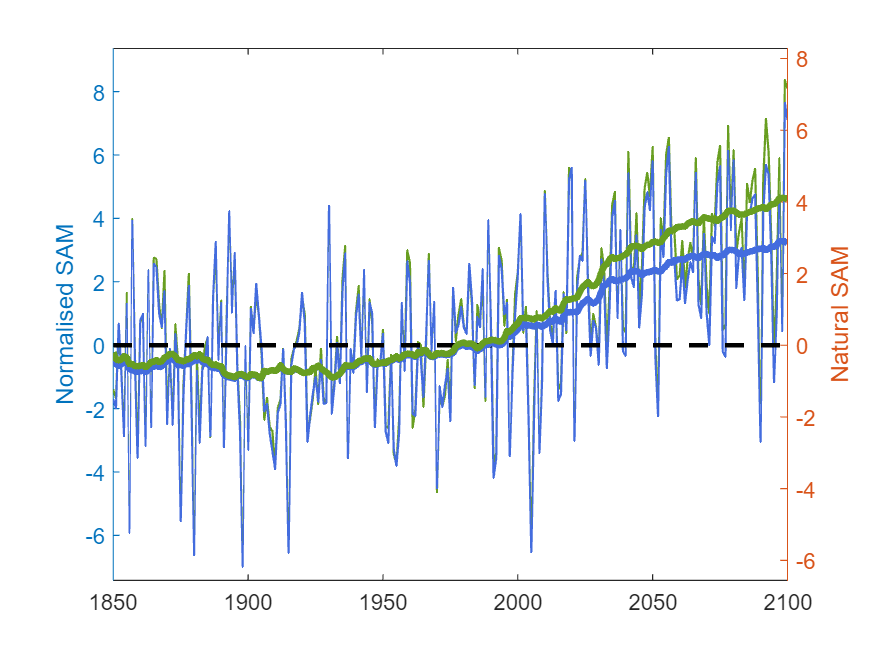

%Make figures. First the normal SAM
figure
yyaxis left;
plot(normalised.Var1, normalised.Var2, 'Color', [0.4078 0.6196 0.1294], 'LineWidth',1);
ylabel('Normalised SAM')
ylim([-7.42 9.36]);
yyaxis right;
plot(natural.Var1, natural.Var2, 'Color', [0.2627 0.4235 0.8705], 'LineWidth',1);
ylabel('Natural SAM')
ylim([-6.56 8.28]);
yZero = zeros(size(100));
line([min(1850), max(2100)], [0, 0], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 2);
hold on
plot(annual_f_65.f_yeartime, d_mov_avg, 'Color', [0.2627 0.4235 0.8705],'LineStyle', '-','LineWidth',3)%dimensional sam
hold on
plot(annual_f_65.f_yeartime, mov_avg, 'Color', [0.4078 0.6196 0.1294],'LineStyle', '-','LineWidth',3)%no dimensional sam (green)
hold off

4. Low emissions scenarios

4. a. Natural non-dimensional SAM index 

% First non-dimensional SAM
%  lat 40
l_fut_40="icmip6_psl_mon_one_ssp126_0-360E_-40N_n_001.nc"

l_fut_40 = "icmip6_psl_mon_one_ssp126_0-360E_-40N_n_001.nc"

l_fut_40=ncread(l_fut_40, "psl")

l_fut_40 = 3012×1
1.0e+05 *

   1.014600000000000
   1.015785000000000
   1.019523984375000
   1.019536015625000
   1.014187968750000
   1.016910000000000
   1.016692031250000
   1.017535000000000
   1.015938984375000
   1.016572031250000


% l_fut_40=l_fut_40*0.875%include this line if calculating weighted values
l_fut_40=l_fut_40/100

l_fut_40 = 3012×1
1.0e+03 *

   1.014600000000000
   1.015785000000000
   1.019523984375000
   1.019536015625000
   1.014187968750000
   1.016910000000000
   1.016692031250000
   1.017535000000000
   1.015938984375000
   1.016572031250000


% I will use the dates from the high emissions model
m_low_future_40=table(f_time,f_yeartime, l_fut_40)%time and msl in one table

m_low_future_40 = 3012×3 table
     f_time     f_yeartime       l_fut_40   
    ________    __________    ______________

    18500101       1850               1014.6
    18500201       1850             1015.785
    18500301       1850       1019.523984375
    18500401       1850       1019.536015625
    18500501       1850        1014.18796875
    18500601       1850              1016.91
    18500701       1850        1016.69203125
    18500801       1850             1017.535
    18500901       1850       1015.938984375
    18501001       1850        1016.57203125
    18501101       1850              1016.04
    18501201       1850       1015.606015625
    18510101       1851       1016.581015625
    18510201       1851        1016.35796875
    18510301       1851               1017.6
    18510401       1851       1016.171015625


%annual future
low_future_40=grpstats(m_low_future_40, "f_yeartime")%calculate annual mean

low_future_40 = 251×4 table
            f_yeartime    GroupCount    mean_f_time     mean_l_fut_40  
            __________    __________    ___________    ________________

    1850       1850           12         18500651      1016.57725260417
    1851       1851           12         18510651      1016.49974609375
    1852       1852           12         18520651      1016.56848958333
    1853       1853           12         18530651      1016.48391276042
    1854       1854           12         18540651      1016.20666015625
    1855       1855           12         18550651      1017.45225260417
    1856       1856           12         18560651      1015.49016927083
    1857       1857           12         18570651  

movStd40Low = movstd(low_future_40.mean_l_fut_40,7)

movStd40Low = 251×1
   0.047369097610787
   0.151319801568649
   0.424305981402409
   0.579726814273121
   0.775986086139674
   0.774209361099491
   0.778132274514554
   0.774948414888037
   0.742367911850117
   0.696417166335271


%calibration period
low_40_interval = low_future_40.mean_l_fut_40(low_future_40.f_yeartime>1960 & low_future_40.f_yeartime<1991)

low_40_interval = 30×1
1.0e+03 *

   1.015541158854167
   1.016299505208333
   1.016840585937500
   1.017093261718750
   1.015846679687500
   1.016551341145833
   1.017683502604167
   1.016589752604167
   1.017003170572917
   1.015251497395833


low_40_interval_mean=mean(low_40_interval)

low_40_interval_mean =      1.016675403428819e+03


low_40_interval_std=std(low_40_interval)

low_40_interval_std =    0.593075609333479


low_future_40_msl=(low_future_40.mean_l_fut_40 - low_40_interval_mean)/low_40_interval_std%normalise data

low_future_40_msl = 251×1
  -0.165494623464903
  -0.296180339074713
  -0.180270177703267
  -0.322877328605558
  -0.790360057288871
   1.309865324288784
  -1.998453720458991
   1.931349724898558
   0.158788175765897
  -0.368268797236187


%Now, lat 65 
l_fut_65="icmip6_psl_mon_one_ssp126_0-360E_-65N_n_001.nc"

l_fut_65 = "icmip6_psl_mon_one_ssp126_0-360E_-65N_n_001.nc"

l_fut_65=ncread(l_fut_65, "psl")

l_fut_65 = 3012×1
1.0e+05 *

   0.992184765625000
   0.989904609375000
   0.983749218750000
   0.982393515625000
   0.991805937500000
   0.982881875000000
   0.984731171875000
   0.986868437500000
   0.989368437500000
   0.984116796875000


%l_fut_65=l_fut_65*0.650%include this line if calculating weighted values
l_fut_65=l_fut_65/100

l_fut_65 = 3012×1
   0.992184765625000
   0.989904609375000
   0.983749218750000
   0.982393515625000
   0.991805937500000
   0.982881875000000
   0.984731171875000
   0.986868437500000
   0.989368437500000
   0.984116796875000


%I will use the dates from the high emissions model

low_future_65=table(f_time,f_yeartime, l_fut_65)%time and msl in one table

low_future_65 = 3012×3 table
     f_time     f_yeartime      l_fut_65   
    ________    __________    _____________

    18500101       1850       992.184765625
    18500201       1850       989.904609375
    18500301       1850        983.74921875
    18500401       1850       982.393515625
    18500501       1850         991.8059375
    18500601       1850          982.881875
    18500701       1850       984.731171875
    18500801       1850         986.8684375
    18500901       1850         989.3684375
    18501001       1850       984.116796875
    18501101       1850       984.977734375
    18501201       1850       987.968515625
    18510101       1851       988.355234375
    18510201       1851         989.9403125
    18510301       1851       981.288515625
    18510401       1851       987.712734375


low_future_65=grpstats(low_future_65, "f_yeartime")%calculate annual mean

low_future_65 = 251×4 table
            f_yeartime    GroupCount    mean_f_time     mean_l_fut_65  
            __________    __________    ___________    ________________

    1850       1850           12         18500651       986.74591796875
    1851       1851           12         18510651      986.900735677083
    1852       1852           12         18520651      984.619244791666
    1853       1853           12         18530651      985.925963541667
    1854       1854           12         18540651      987.398111979167
    1855       1855           12         18550651      984.945104166667
    1856       1856           12         18560651      989.383151041667
    1857       1857           12         18570651  

movStd65Low = movstd(low_future_65.mean_l_fut_65,7)

movStd65Low = 251×1
   1.044107587657921
   1.087290024238116
   1.122451686628394
   1.612436091763806
   2.091565768303213
   2.055752851445701
   2.144778704710992
   2.228635242019400
   2.227845134696774
   2.305217946655269


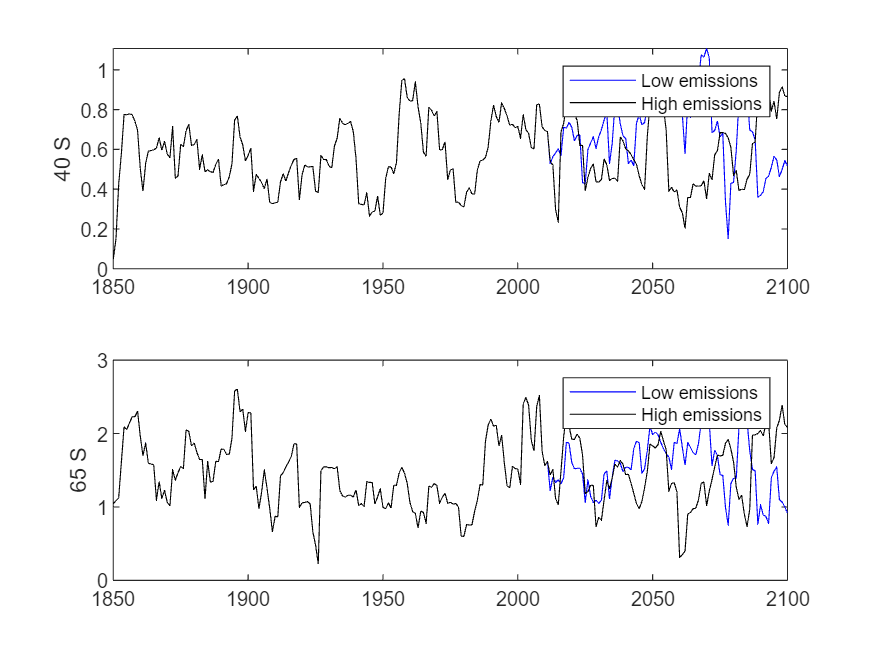

tiledlayout(2,1)
nexttile;
plot(annual_f_40.f_yeartime, movStd40Low, 'b')
hold on
plot(annual_f_40.f_yeartime, movStd40High, 'k')
ylabel('40 S')
legend('Low emissions', 'High emissions');
nexttile;
plot(low_future_65.f_yeartime ,movStd65Low, 'b')
hold on
plot(low_future_65.f_yeartime, movStd65High, 'k')
ylabel('65 S')
legend('Low emissions', 'High emissions');

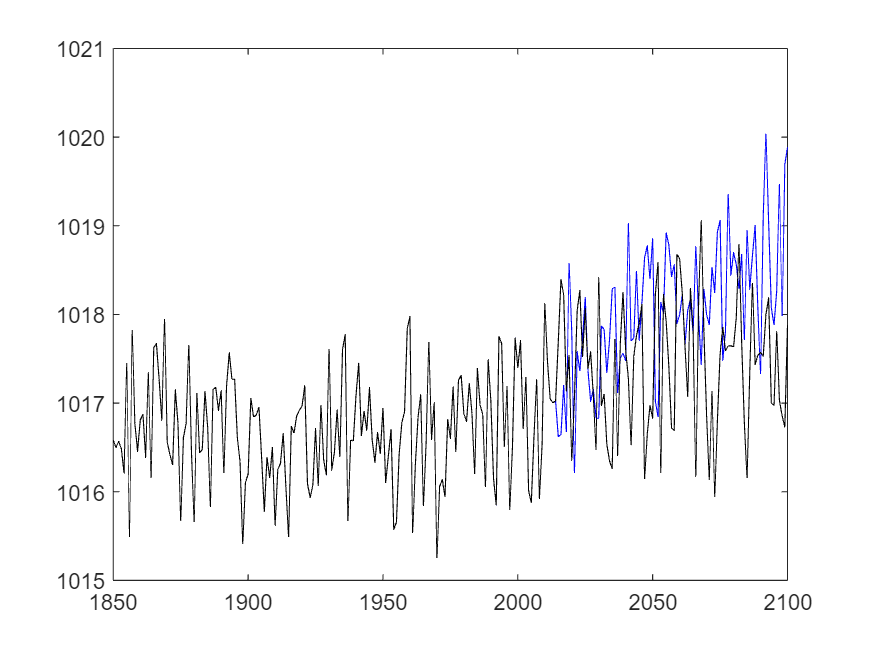

tiledlayout(1,1)
nexttile;
plot(annual_f_40.f_yeartime, annual_f_40.mean_annual_f_msl_40, 'b')
hold on
plot(low_future_40.f_yeartime, low_future_40.mean_l_fut_40, 'k')

low_65_interval = low_future_65.mean_l_fut_65(low_future_65.f_yeartime>1960 & low_future_65.f_yeartime<1991)

low_65_interval = 30×1
   9.861172265625001
   9.869245442708333
   9.855457682291666
   9.861060221354165
   9.859544010416666
   9.849989908854164
   9.839849088541667
   9.854036718750002
   9.844543098958335
   9.878813476562501


low_65_interval_mean=mean(low_65_interval)

low_65_interval_mean =      9.853320475260417e+02


low_65_interval_std=std(low_65_interval)

low_65_interval_std =    1.144564618331935


low_future_65_msl=(low_future_65.mean_l_fut_65 - low_65_interval_mean)/low_65_interval_std%normalise data

low_future_65_msl = 251×1
   1.235291061826341
   1.370554467538597
  -0.622771945732591
   0.518901253902543
   1.805109488825497
  -0.338070348477926
   3.539427526188040
  -2.039749974487389
   0.409717861444621
   2.550844288762392


%Calculate the SAM
low_normal_future_sam=low_future_40_msl- low_future_65_msl

low_normal_future_sam = 251×1
  -1.400785685291244
  -1.666734806613309
   0.442501768029324
  -0.841778582508102
  -2.595469546114368
   1.647935672766710
  -5.537881246647030
   3.971099699385947
  -0.250929685678724
  -2.919113085998579


%combine in table year and normal sam
low_normal_f_sam=table(low_future_65.f_yeartime, low_normal_future_sam)

low_normal_f_sam = 251×2 table
    Var1           Var2       
    ____    __________________

    1850     -1.40078568529124
    1851     -1.66673480661331
    1852     0.442501768029324
    1853    -0.841778582508102
    1854     -2.59546954611437
    1855      1.64793567276671
    1856     -5.53788124664703
    1857      3.97109969938595
    1858    -0.250929685678724
    1859     -2.91911308599858
    1860     0.712320543190073
    1861     0.921846308819211
    1862     -2.68459227220109
    1863      2.36527008341161
    1864     -2.41138400480117
    1865      2.76263185495197


low_normal_f_sam.Properties.VariableNames=["Year", "SAM"]%rename variables

low_normal_f_sam = 251×2 table
    Year           SAM        
    ____    __________________

    1850     -1.40078568529124
    1851     -1.66673480661331
    1852     0.442501768029324
    1853    -0.841778582508102
    1854     -2.59546954611437
    1855      1.64793567276671
    1856     -5.53788124664703
    1857      3.97109969938595
    1858    -0.250929685678724
    1859     -2.91911308599858
    1860     0.712320543190073
    1861     0.921846308819211
    1862     -2.68459227220109
    1863      2.36527008341161
    1864     -2.41138400480117
    1865      2.76263185495197


%general stats
%trend_low_normal_f_sam=low_normal_f_sam(low_normal_f_sam.Year>1950 & low_normal_f_sam.Year<2100,:);
%p10=polyfit(trend_low_dim_f_sam.Year, trend_low_dim_f_sam.("Dimensional SAM"),1);
%trend_p10=p10(1)


%historical sd
low_sd = low_normal_f_sam(low_normal_f_sam.Year>1850 & low_normal_f_sam.Year<1951,:)

low_sd = 100×2 table
    Year           SAM        
    ____    __________________

    1851     -1.66673480661331
    1852     0.442501768029324
    1853    -0.841778582508102
    1854     -2.59546954611437
    1855      1.64793567276671
    1856     -5.53788124664703
    1857      3.97109969938595
    1858    -0.250929685678724
    1859     -2.91911308599858
    1860     0.712320543190073
    1861     0.921846308819211
    1862     -2.68459227220109
    1863      2.36527008341161
    1864     -2.41138400480117
    1865      2.76263185495197
    1866      2.71455676094445


historical_low_sd=std(low_sd.SAM)

historical_low_sd =    2.191702216141447


% standard deviation 1990 to 2100
fut_low_sd = low_normal_f_sam(low_normal_f_sam.Year>1990 &low_normal_f_sam.Year<2100,:)

fut_low_sd = 109×2 table
    Year           SAM        
    ____    __________________

    1991     -3.66422845648695
    1992     -3.41447010810114
    1993      3.06018658147455
    1994       2.6769917358656
    1995      0.61788118357518
    1996      1.43865218597384
    1997     -3.42282025665558
    1998    -0.850466016474265
    1999      1.61108067706502
    2000      2.30306133715469
    2001      4.03545259678164
    2002     0.398875895450176
    2003      1.19482638620026
    2004     -2.33625357359794
    2005     -5.69103794857441
    2006     -1.83630304629025


future_low_Sd=std(fut_low_sd.SAM)

future_low_Sd =    2.671320743783136


4. b. Natural (dimensional) annual resolution SAM index

%=====================================================================
%dimensional low emissions sam index 
% lat 40
d_low_future_40_msl=(low_future_40.mean_l_fut_40-low_40_interval_mean)

d_low_future_40_msl = 251×1
  -0.098150824652862
  -0.175657335069332
  -0.106913845486019
  -0.191490668402707
  -0.468743272569441
   0.776849175347365
  -1.185234157985974
   1.145436414930259
   0.094173394097311
  -0.218411241319359


% lat 65
d_low_future_65_msl=(low_future_65.mean_l_fut_65-low_65_interval_mean)

d_low_future_65_msl = 251×1
   1.413870442708117
   1.568688151041442
  -0.712802734375259
   0.593916015624927
   2.066064453124909
  -0.386943359374982
   4.051103515624959
  -2.334625651041733
   0.468948567708139
   2.919606119791524


%calculate dimensional SAM
low_d_future_sam=d_low_future_40_msl-d_low_future_65_msl

low_d_future_sam = 251×1
  -1.512021267360979
  -1.744345486110774
   0.605888888889240
  -0.785406684027635
  -2.534807725694350
   1.163792534722347
  -5.236337673610933
   3.480062065971993
  -0.374775173610828
  -3.138017361110883


%combine in table year and normal sam
low_d_f_sam=table(low_future_65.f_yeartime, low_d_future_sam)

low_d_f_sam = 251×2 table
    Var1           Var2       
    ____    __________________

    1850     -1.51202126736098
    1851     -1.74434548611077
    1852      0.60588888888924
    1853    -0.785406684027635
    1854     -2.53480772569435
    1855      1.16379253472235
    1856     -5.23633767361093
    1857      3.48006206597199
    1858    -0.374775173610828
    1859     -3.13801736111088
    1860      0.69183940972232
    1861     0.869899305555577
    1862     -2.80760720486114
    1863      2.08532899305555
    1864     -2.27669574652759
    1865      2.27760763888921


low_d_f_sam.Properties.VariableNames=["Year", "Dimensional SAM"]%rename variables

low_d_f_sam = 251×2 table
    Year     Dimensional SAM  
    ____    __________________

    1850     -1.51202126736098
    1851     -1.74434548611077
    1852      0.60588888888924
    1853    -0.785406684027635
    1854     -2.53480772569435
    1855      1.16379253472235
    1856     -5.23633767361093
    1857      3.48006206597199
    1858    -0.374775173610828
    1859     -3.13801736111088
    1860      0.69183940972232
    1861     0.869899305555577
    1862     -2.80760720486114
    1863      2.08532899305555
    1864     -2.27669574652759
    1865      2.27760763888921


trend_low_dim_f_sam=low_d_f_sam(low_d_f_sam.Year>1950 & low_d_f_sam.Year<2100,:)

trend_low_dim_f_sam = 149×2 table
    Year     Dimensional SAM  
    ____    __________________

    1951     -2.40851866319406
    1952     -2.72730121527775
    1953     -0.37510720486091
    1954      -2.8998077256939
    1955     -3.36573220486116
    1956     -2.42471657986118
    1957      1.18799175347215
    1958    -0.717405381944218
    1959      2.33975607638899
    1960      1.76851258680563
    1961     -1.91942361111103
    1962     -1.96839496527764
    1963    -0.048538194444177
    1964    -0.356116319444254
    1965     -1.45107725694447
    1966     0.208994357639199


%historical sd
low_d_sd = low_d_future_sam(low_d_f_sam.Year >1850 & low_d_f_sam.Year<1951,:)

low_d_sd = 100×1
  -1.744345486110774
   0.605888888889240
  -0.785406684027635
  -2.534807725694350
   1.163792534722347
  -5.236337673610933
   3.480062065971993
  -0.374775173610828
  -3.138017361110883
   0.691839409722320


historical_low_sd=std(low_d_sd)

historical_low_sd =    2.034321991532410


% standard deviation 1990 to 2100
fut_d_low_sd = low_d_future_sam(low_d_f_sam.Year>1990 & low_d_f_sam.Year<2100,:)

fut_d_low_sd = 109×1
  -3.698870225694350
  -3.140719184027830
   2.501162326388680
   2.134176649305459
   0.862015190972102
   1.170993055555414
  -3.100374131944477
  -0.807203559027698
   0.857913628472147
   1.962444878472297



future_low_Sd=std(fut_d_low_sd)

future_low_Sd =    2.394407462586690


%combine dimensional and normal in one table
low_future_sams=table(low_d_f_sam.Year,low_d_f_sam.("Dimensional SAM"),low_normal_f_sam.SAM)

low_future_sams = 251×3 table
    Var1           Var2                  Var3       
    ____    __________________    __________________

    1850     -1.51202126736098     -1.40078568529124
    1851     -1.74434548611077     -1.66673480661331
    1852      0.60588888888924     0.442501768029324
    1853    -0.785406684027635    -0.841778582508102
    1854     -2.53480772569435     -2.59546954611437
    1855      1.16379253472235      1.64793567276671
    1856     -5.23633767361093     -5.53788124664703
    1857      3.48006206597199      3.97109969938595
    1858    -0.374775173610828    -0.250929685678724
    1859     -3.13801736111088     -2.91911308599858
    1860      0.69183940972232     0.712320543190073
    1861     0.869899305555577     0.921846308819211
    1862     -2.80760720486114     -2.68459227220109
    1863      2.08532899305555      2.36527008341161
    1864     -2.276

low_future_sams.Properties.VariableNames=["Year", "Dimensional SAM", "SAM"]

low_future_sams = 251×3 table
    Year     Dimensional SAM             SAM        
    ____    __________________    __________________

    1850     -1.51202126736098     -1.40078568529124
    1851     -1.74434548611077     -1.66673480661331
    1852      0.60588888888924     0.442501768029324
    1853    -0.785406684027635    -0.841778582508102
    1854     -2.53480772569435     -2.59546954611437
    1855      1.16379253472235      1.64793567276671
    1856     -5.23633767361093     -5.53788124664703
    1857      3.48006206597199      3.97109969938595
    1858    -0.374775173610828    -0.250929685678724
    1859     -3.13801736111088     -2.91911308599858
    1860      0.69183940972232     0.712320543190073
    1861     0.869899305555577     0.921846308819211
    1862     -2.80760720486114     -2.68459227220109
    1863      2.08532899305555      2.36527008341161
    1864     -2.276

writetable(low_future_sams, 'low emissions sams.csv')

%Correlation coefficient 
f_low = corr(low_future_sams.("Dimensional SAM"), low_future_sams.SAM)

f_low =    0.994875569214588


f_low_slope = polyfit(low_future_sams.("Dimensional SAM"), low_future_sams.SAM,1);
f_low_slope = f_low_slope(1)

f_low_slope =    1.113684892722484


% scale  natural sam to include in the same plot as normalised sam. They
% are both in same table, can do it at the same time
ri_low_future = low_future_sams(low_normal_f_sam.Year>1960 & low_normal_f_sam.Year<1991, :)

ri_low_future = 30×3 table
    Year     Dimensional SAM             SAM        
    ____    __________________    __________________

    1961     -1.91942361111103     -2.59848561056997
    1962     -1.96839496527764     -2.02516754193356
    1963    -0.048538194444177    0.0917918275998182
    1964    -0.356116319444254    0.0283440961030162
    1965     -1.45107725694447     -1.94107930671343
    1966     0.208994357639199    0.0818052117208904
    1967      2.35523784722227      2.87676975161834
    1968     -0.15727517361131    -0.206995864302686
    1969      1.20550477430538      1.31953127457021
    1970     -3.97320616319462     -4.62819441342232
    1971     -1.14792621527761     -1.50277759479408
    1972     -1.71840798611095     -1.93863776713416
    1973     -1.12122699652787     -1.57436118770362
    1974    -0.650543402777657    -0.454757438044782
    1975     -2.124391

%calculate slope
b2 = polyfit(ri_low_future.("Dimensional SAM"), ri_low_future.SAM, 1)

b2 = 1×2
   1.130426787620545  -0.000000000000006


slope_2=b2(1)

slope_2 =    1.130426787620545


max(low_future_sams.("Dimensional SAM"))

ans =    5.845218315971692


min(low_future_sams.("Dimensional SAM"))

ans =   -6.175816840277889


max(low_future_sams.SAM)

ans =    7.040871078988684


min(low_future_sams.SAM)

ans =   -6.421133657118212


%moving average
lowmov_avg=movmean(low_future_sams.("SAM"), 50);
lowd_mov_avg=movmean(low_future_sams.("Dimensional SAM"), 50);

### Plot low emissions SAMs scaled

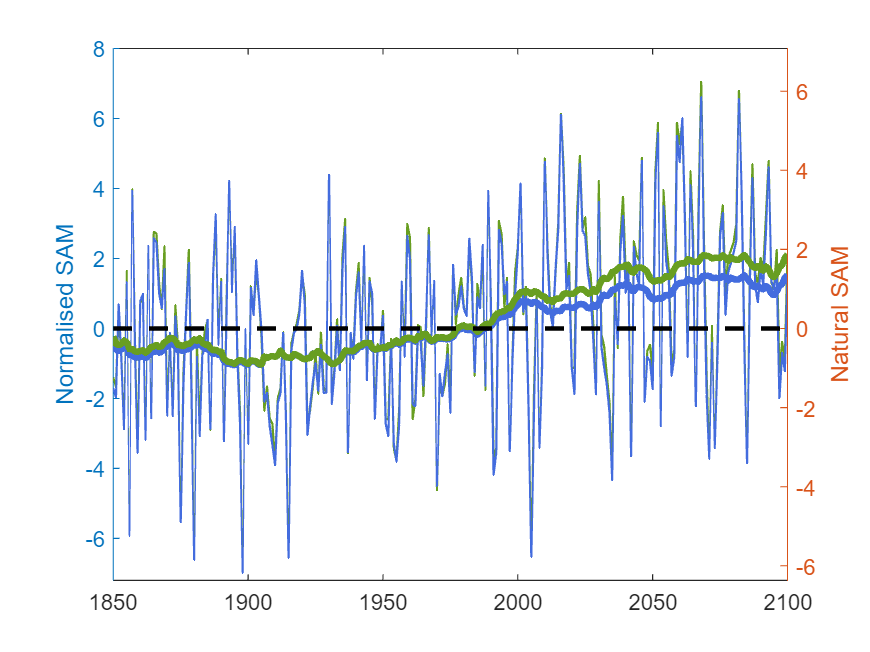

figure
yyaxis left
plot(low_future_sams.Year, low_future_sams.SAM, 'Color', [0.4078 0.6196 0.1294], 'LineWidth',1)%normalised sam
ylabel('Normalised SAM')
ylim([-7.2 8]);
yyaxis right
plot(low_future_sams.Year, low_future_sams.("Dimensional SAM"),'Color', [0.2627 0.4235 0.8705],'LineWidth', 1)%no dimensional sam
ylabel('Natural SAM')
ylim([-6.37 7.08]);
hold on
plot(low_future_sams.Year, lowd_mov_avg, 'Color', [0.2627 0.4235 0.8705],'LineStyle','-', 'LineWidth',3)%dimensional sam
hold on 
plot(low_future_sams.Year ,lowmov_avg, 'Color', [0.4078 0.6196 0.1294],'LineStyle','-', 'LineWidth',3)%non-dimensional sam (green)
yZero = zeros(size(100));
line([min(1850), max(2100)], [0, 0], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 2);
hold off;